# 3. Heat Transfer -internalHeatSource

[`internalHeatSource(thermalmodel,heatSourceValue)`](https://ww2.mathworks.cn/help/pde/ug/pde.thermalmodel.internalheatsource.html#d120e52447)`：`指定热模型的内部热源。此语法声明整个几何都是热源。

[`internalHeatSource(thermalmodel,heatSourceValue,RegionType,RegionID)`](https://ww2.mathworks.cn/help/pde/ug/pde.thermalmodel.internalheatsource.html#d120e52482)`：` 指定`RegionType`带有ID号的类型的几何区域`RegionID`作为热源。始终`heatSourceValue`先指定 ，然后再指定 `RegionType`和`RegionID`。

[`heatSource = internalHeatSource(``___``)`](https://ww2.mathworks.cn/help/pde/ug/pde.thermalmodel.internalheatsource.html#d120e52512)`：`返回热源对象。

3.1 **在整个几何上指定内部热量产生**

- 创建瞬态热模型。

% Thermalmodel = createpde('thermal','transient');

- 导入几何。

% geom = multicylinder([20,25,35],20,'Void',[1,0,0]);
% Thermalmodel.Geometry = geom;
% pdegplot(Thermalmodel);

- 设置物性参数

% thermalProperties(Thermalmodel,'ThermalConductivity',0.2,...
%                                'MassDensity',2700e-9,... 
%                                'SpecificHeat',920)
%                            

- 内热源

% internalHeatSource(thermalmodel,2e-4)

3.2 **将二维几何的面指定为热源**

- 创建稳态热模型。

% ThermalModel = createpde('thermal','transient');

- 创建几何。

% SQ1 = [3; 4; 0; 3; 3; 0; 0; 0; 3; 3];
% D1 = [2; 4; 0.5; 1.5; 2.5; 1.5; 1.5; 0.5; 1.5; 2.5];
% gd = [SQ1 D1];
% sf = 'SQ1+D1';
% ns = char('SQ1','D1');
% ns = ns';
% dl = decsg(gd,sf,ns);
% 
% aa=geometryFromEdges(ThermalModel,dl);
% pdegplot(aa);

- Set thermal conductivity to 50, mass density to 2500, and specific heat to 600.

% thermalProperties(ThermalModel,'ThermalConductivity',50, ...
%                                'MassDensity',2500, ...
%                                'SpecificHeat',600);

- Specify that face 1 generates heat at 25.

% internalHeatSource(ThermalModel,25,'Face',1)

3.3 非恒定热源

创建用于瞬态分析的热模型，并包括几何体。该几何形状是具有圆形横截面的杆。2-D模型是一个矩形条，其*y*维度从对称轴延伸到外表面，并且其*x*维度在杆的实际长度上延伸。

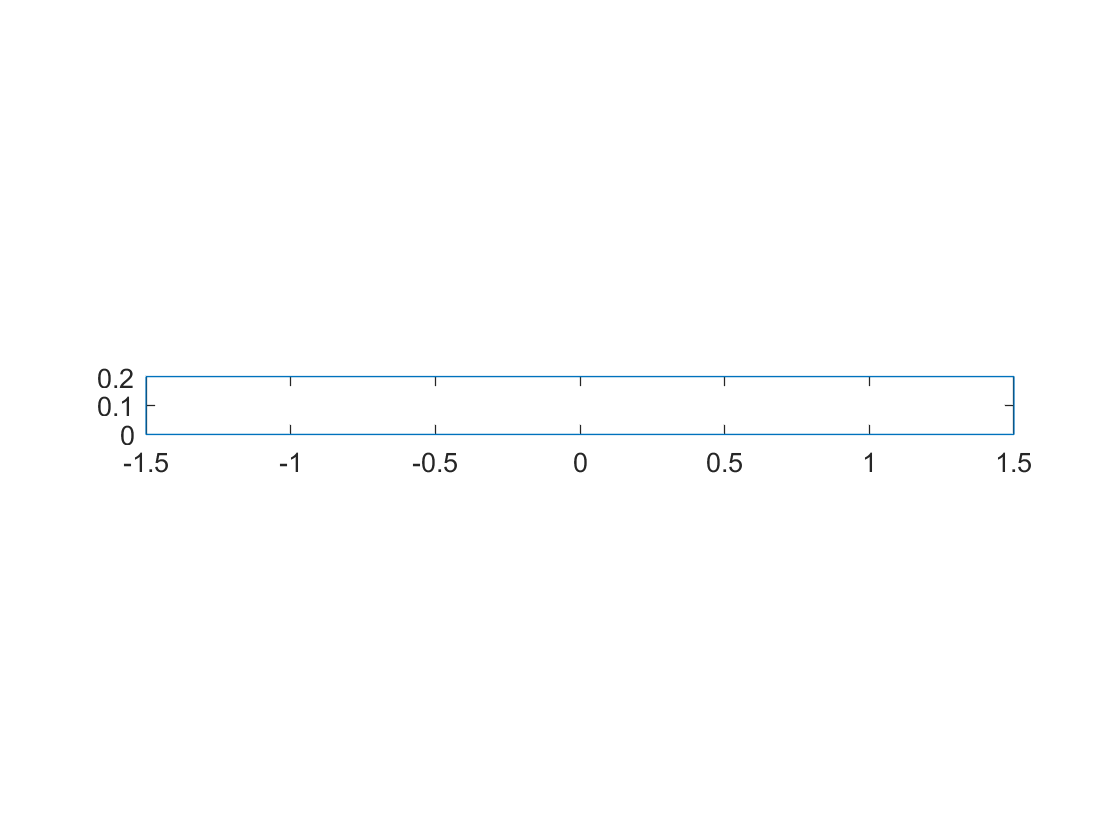

Thermalmodel = createpde('thermal','transient');
g = decsg([3 4 -1.5 1.5 1.5 -1.5 0 0 .2 .2]');
aa=geometryFromEdges(Thermalmodel,g);
pdegplot(aa);

由于放射性衰变，在棒内产生热量。因此，整个几何结构是内部非线性热源，并且可以由*y*坐标的函数表示，例如，*q *= 2000 *y*。

q = @(location,state)2000*location.y;

指定瞬态模型的内部热源。

internalHeatSource(Thermalmodel,q)

ans =   HeatSourceAssignment - 属性:

    RegionType: 'face'
      RegionID: 1
    HeatSource: @(location,state)2000*location.y
